%% === Setup ===
clc; clear;

% Path to Python (must have RDKit)
pythonExecutable = 'C:\Users\...\AppData\Local\Programs\Python\Python311\python.exe';
pyenv('Version', pythonExecutable);

% Load large dataset
alldata = readtable('LogP_LogS.csv');

refdata = readtable('Ref_Data.csv');


% Extract SMILES
smiles_all = alldata.SMILES';
smiles_ref = refdata.SMILES';

% Convert to Python lists
pySmiles_all = py.list(smiles_all);
pySmiles_ref = py.list(smiles_ref);

%% === Compute RDKit Fingerprints via Python ===
fprintf('Computing fingerprints using RDKit (Python)...\n');

Computing fingerprints using RDKit (Python)...



fp_all_py = pyrunfile('Compute_Fingerprints.py', 'fingerprints', smilesList=pySmiles_all);
fp_ref_py = pyrunfile('Compute_Fingerprints.py', 'fingerprints', smilesList=pySmiles_ref);

fp_all = logical(fp_all_py);
fp_ref = logical(fp_ref_py);

%% === Transfer to GPU ===
fp_all_gpu = gpuArray(fp_all);
fp_ref_gpu = gpuArray(fp_ref);

nAll = size(fp_all_gpu, 1);
nRef = size(fp_ref_gpu, 1);

%% === GPU-Accelerated Tanimoto Similarity ===
fprintf('Computing Tanimoto similarity on GPU...\n');

Computing Tanimoto similarity on GPU...



% Precompute bit counts
bitCounts_all = sum(fp_all_gpu, 2);  % (nAll x 1)
bitCounts_ref = sum(fp_ref_gpu, 2);  % (nRef x 1)

% Compute intersection matrix
intersection = fp_all_gpu * fp_ref_gpu';  % (nAll x nRef)

% Compute union matrix
union = bitCounts_all + bitCounts_ref' - intersection;  % (nAll x nRef)

% Tanimoto similarity
simMatrix_gpu = intersection ./ union;
simMatrix_gpu(union == 0) = NaN;

simMatrix = gather(simMatrix_gpu);

%% === Match and Save ===
threshold = 0.30;
[matchRows, ~] = find(simMatrix >= threshold);
uniqueMatches = unique(matchRows);

MatchedMolecules = alldata(uniqueMatches, :);
writetable(MatchedMolecules, 'matched_molecules.csv');
fprintf('Found and saved %d similar molecules.\n', height(MatchedMolecules));

Found and saved 4 similar molecules.




%% === Combine with Reference Data (Matched First) and Save ===
fprintf('Combining matched molecules with reference data (matched first)...\n');

Combining matched molecules with reference data (matched first)...



% Ensure matched molecules follow refdata column order
refCols = refdata.Properties.VariableNames;
MatchedMolecules = MatchedMolecules(:, refCols);

% Append reference molecules after matched molecules
combinedCandidates = [MatchedMolecules; refdata];

% Deduplicate based on InChIKey, but preserve order (first match wins)
[~, uniqueIdx] = unique(combinedCandidates.InChIKey, 'stable');
combinedCandidates = combinedCandidates(uniqueIdx, :);

% Save final combined dataset
writetable(combinedCandidates, 'SGLT2_Candidates.csv');
fprintf('Saved combined candidates (%d molecules) to SGLT2_Candidates.csv\n', height(combinedCandidates));

Saved combined candidates (7 molecules) to SGLT2_Candidates.csv




%% === Visualize Combined Candidates with CompoundID ===
fprintf('Drawing molecules in SGLT2_Candidates.csv...\n');

Drawing molecules in SGLT2_Candidates.csv...


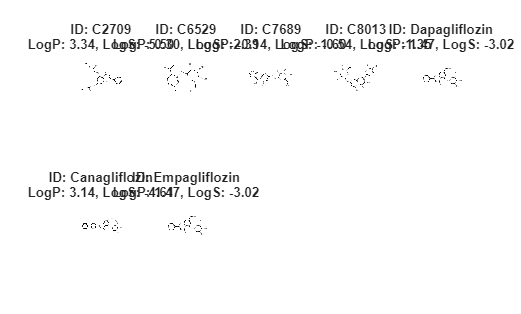


% Extract required data
smilesList = combinedCandidates.SMILES;
logPList   = combinedCandidates.logP;
logSList   = combinedCandidates.logS;
compoundIDs = combinedCandidates.CompoundID;

% Define layout
numToDraw = height(combinedCandidates);
cols = 5;
rows = ceil(numToDraw / cols);

figure('Name', 'SGLT2 Candidates', 'NumberTitle', 'off');
for i = 1:numToDraw
    subplot(rows, cols, i);
    try
        % Draw molecule
        RDKitDraw(pythonExecutable, smilesList{i}, 1, logPList(i), logSList(i));
        
        % Add title with CompoundID
        title({
            sprintf('ID: %s', string(compoundIDs{i})), ...
            sprintf('LogP: %.2f, LogS: %.2f', logPList(i), logSList(i))
        }, 'Interpreter', 'none', 'FontSize', 8);
    catch ME
        warning('Failed to draw molecule %d (ID: %s): %s', ...
            i, string(compoundIDs{i}), ME.message);
        imshow(ones(100)); 
        title(sprintf('Draw Error\nID: %s', string(compoundIDs{i})), 'FontSize', 8);
    end
end